# 线性规划

## 问题一

将边长为a的一块正方形铁皮的四角各截去一个大小相同的小正方形，然后将四边折起做成一个无盖的方盒，试建立以小正方形的边长b为变量，使该方盒的容积最大的优化问题的数学模型。

经分析可得到数学模型


$$\begin{array}{l}
\min \;f\left(b\right)={b\left(a-2b\right)}^2 \\
0<b<\frac{a}{2}
\end{array}$$


答案：$b=\frac{a}{6}$

% 基于问题的最优化任务，这玩意只能求数值解，无语了。。。凑合着用用吧
clc,clear
a=100;
upper=a/2;

% 创建优化变量
b2 = optimvar("b","LowerBound",0,"UpperBound",upper);

% 设置求解器的初始起点
initialPoint2.b = zeros(size(b2));

% 创建问题
problem = optimproblem("ObjectiveSense","Maximize");

% 定义问题目标
problem.Objective = b2*(a-2*b2)^2;

% 求解问题
[cal_b,objectiveValue] = solve(problem,initialPoint2);

将使用 fmincon 求解问题。

可能存在局部最小值。满足约束。

fmincon 已停止，因为当前步长小于
步长容差值并且在约束容差值范围内满足约束。

<停止条件详细信息>



% 显示结果
cal_b

cal_b = 包含以下字段的 struct :
    b: 16.6667


objectiveValue

objectiveValue = 7.4074e+04


% 清除变量
clearvars b2 initialPoint2 objectiveValue
% 检验一下
ans_b=a/6;
abs(cal_b.b-ans_b)<1e-5

ans = logical
   1


与答案一致

用符号工具箱试试

syms a b
% 目标函数
f=b*(a-2*b)^2;
% 约束
constrain=[b>0;
    b<a/2];
% f对b求导
f_diff=diff(f,b)==0;
solution=solve(f_diff)

$$solution = \left(\begin{array}{c} \frac{a}{2}\\ \frac{a}{6} \end{array}\right)$$

subs(constrain,b,solution)

$$ans = \left(\begin{array}{c} 0<\frac{a}{2}\\ 0<\frac{a}{6}\\ \frac{a}{2}<\frac{a}{2}\\ \frac{a}{6}<\frac{a}{2} \end{array}\right)$$

显然a/2不对，选a/6

## 问题三

利用单纯形法求解以下线性规划问题。


$$\begin{array}{l}
\min \;f\left(x\right)=-2x_1 +x_2 -x_3 \\
3x_1 +x_2 +x_3 \le 60\\
x_1 -x_2 +2x_3 \le 10\\
x_1 +x_2 -x_3 \le 20\\
x_1 ,x_2 ,x_3 \ge 0
\end{array}$$


答案：$\left(x_1 ,x_2 ,x_3 \right)=\left(15,5,0\right),f=-25$

% 基于问题解法
clc,clear

% 创建优化变量
x13 = optimvar("x1","LowerBound",0);
x23 = optimvar("x2","LowerBound",0);
x3 = optimvar("x3","LowerBound",0);

% 设置求解器的初始起点
initialPoint3.x1 = zeros(size(x13));
initialPoint3.x2 = zeros(size(x23));
initialPoint3.x3 = zeros(size(x3));

% 创建问题
problem2 = optimproblem;

% 定义问题目标
problem2.Objective = -2*x13+x23-x3;

% 定义问题约束
problem2.Constraints.constraint1 = 3*x13+x23+x3 <= 60;
problem2.Constraints.constraint2 = x13-x23+2*x3 <= 10;
problem2.Constraints.constraint3 = x13+x23-x3 <= 20;

% 求解问题
[solution2,objectiveValue2] = solve(problem2,initialPoint3);

将使用 linprog 求解问题。

找到最优解。




% 显示结果
solution2

solution2 = 包含以下字段的 struct :
    x1: 15
    x2: 5.0000
    x3: 0


objectiveValue2

objectiveValue2 = -25


% 清除变量
clearvars x13 x23 x3 initialPoint3 objectiveValue2

与答案一致

用自定义的单纯形法试试

% 定义各参数
c=[-2 1 -1 0 0 0];
b=[60 10 20];
A=[3 1 1 1 0 0;
    1 -1 2 0 1 0;
    1 1 -1 0 0 1];
x=simplex(c,A,b)

x =    15.0000
    5.0000
         0
   10.0000
         0
         0


莫得问题

再看看书上的例题 例2-10

答案(0,7,0,5/12,1)

c=[-5 -10 0 0 0];
b=[1 1 8];
A=[1/14 1/7 1 0 0;
    1/7 1/12 0 1 0;
    1 1 0 0 1];
x=simplex(c,A,b,[3 4 5])

x =          0
    7.0000
         0
    0.4167
    1.0000


答案没错吧，但是看直接使用默认方法，设置前三个变量为基变量的

x=simplex(c,A,b)

x =     2.0000
    6.0000
         0
    0.2143
         0


然后不出意外的出意外了。或许是编写的默认方法程序错了？验算结果显示计算是没问题的

莫非单纯形矩阵如果是典式了就不能再化简为典式？可是从原理上讲不通。

一筹莫展。。。

用最优化工具箱试试

% 创建优化变量
x14 = optimvar("x1","LowerBound",0);
x24 = optimvar("x2","LowerBound",0);

% 设置求解器的初始起点
initialPoint4.x1 = zeros(size(x14));
initialPoint4.x2 = zeros(size(x24));

% 创建问题
problem4 = optimproblem;

% 定义问题目标
problem4.Objective = -5*x14-10*x24;

% 定义问题约束
problem4.Constraints.constraint1 = x14/14+x24/7 <= 1;
problem4.Constraints.constraint2 = x14/7+x24/12 <= 1;
problem4.Constraints.constraint3 = x14+x24 <= 8;

% 显示问题信息
show(problem4);


  OptimizationProblem : 

	Solve for:
       x1, x2

	minimize :
       -5*x1 - 10*x2


	subject to constraint1:
       0.071429*x1 + 0.14286*x2 <= 1

	subject to constraint2:
       0.14286*x1 + 0.083333*x2 <= 1

	subject to constraint3:
       x1 + x2 <= 8

	variable bounds:
       0 <= x1

       0 <= x2




% 求解问题
[solution3,objectiveValue4,reasonSolverStopped] = solve(problem4,initialPoint4);

将使用 linprog 求解问题。

找到最优解。




% 显示结果
solution3

solution3 = 包含以下字段的 struct :
    x1: 0
    x2: 7


reasonSolverStopped

reasonSolverStopped =     OptimalSolution


objectiveValue4

objectiveValue4 = -70


% 清除变量
clearvars x14 x24 initialPoint4 reasonSolverStopped objectiveValue4

工具箱结果显示的答案和书本相同

c=[-5 -10 0 0 0];
b=[1 1 8];
A=[1/14 1/7 1 0 0;
    1/7 1/12 0 1 0;
    1 1 0 0 1];
x=simplex(c,A,b)

x =     2.0000
    6.0000
         0
    0.2143
         0


## 问题四

用分支定界法求解整数线性规划问题

$\begin{array}{l}
\min \;Z=x_1 +4x_2 \\
2x_1 +x_2 \le 8\\
x_1 +2x_2 \ge 6\\
x_1 ,x_2 \ge 0
\end{array}$且$x_1 ,x_2$取整数

答案：$x=\left(3,2\right),Z=11$

% 基于问题

% 创建优化变量
x12 = optimvar("x1","Type","integer","LowerBound",0);
x22 = optimvar("x2","Type","integer","LowerBound",0);

% 设置求解器的初始起点
initialPoint.x1 = zeros(size(x12));
initialPoint.x2 = zeros(size(x22));

% 创建问题
problem3 = optimproblem;

% 定义问题目标
problem3.Objective = x12+4*x22;

% 定义问题约束
problem3.Constraints.constraint1 = 2*x12+x22 <= 8;
problem3.Constraints.constraint2 = x12+2*x22 >= 6;

% 设置非默认求解器选项
options = optimoptions("intlinprog","Display","final");

% 求解问题
[solution,objectiveValue3] = solve(problem3,initialPoint,"Solver","intlinprog",...
    "Options",options);

将使用 intlinprog 求解问题。

找到最优解。

Intlinprog 在根节点处停止，因为目标值在最优值的间隙容差范围内，options.AbsoluteGapTolerance = 1e-06。intcon 变量是容差范围内的整数，options.ConstraintTolerance = 1e-06。




% 显示结果
solution

solution = 包含以下字段的 struct :
    x1: 2
    x2: 2


objectiveValue3

objectiveValue3 = 10


% 清除变量
clearvars x12 x22 initialPoint options objectiveValue3

翻车了。。。。

经验算，给的答案不是最优解，用MATLAB求解的结果更优（虽然不知道这是不是最优的。。。）

发现了，原答案没有考虑完整，应该先对x2进行分枝，再对x1分枝，这样就能得到正确答案了

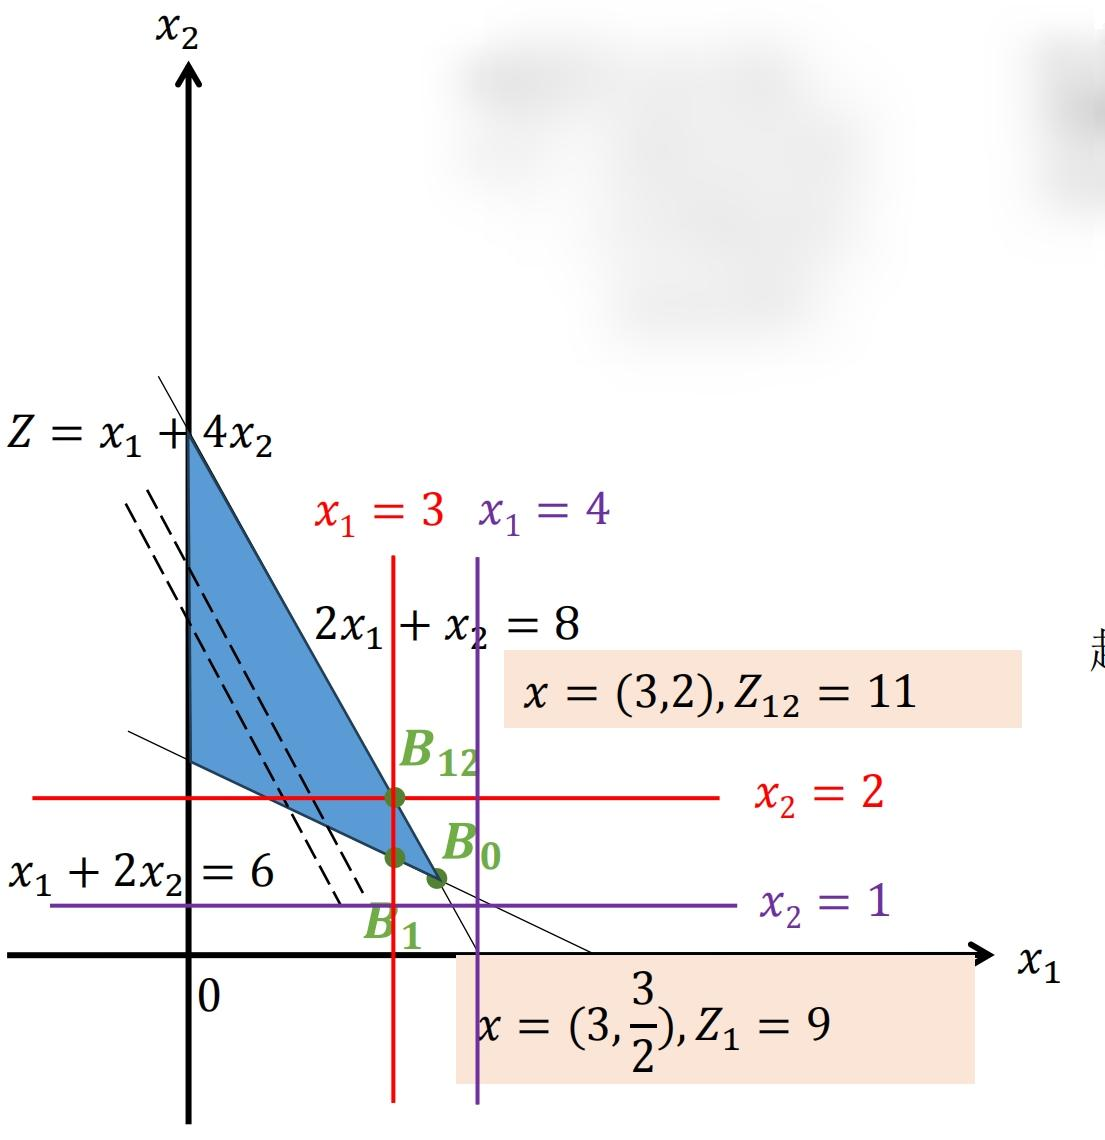

% 创建优化变量
x15 = optimvar("x1","Type","integer","LowerBound",0,"UpperBound",8);
x25 = optimvar("x2","Type","integer","LowerBound",0,"UpperBound",4);

% 设置求解器的初始起点
initialPoint5.x1 = zeros(size(x15));
initialPoint5.x2 = zeros(size(x25));

% 创建问题
problem5 = optimproblem;

% 定义问题目标
problem5.Objective = -10*x15-20*x25;

% 定义问题约束
problem5.Constraints = 5*x15+8*x25 <= 60;

% 设置非默认求解器选项
options2 = optimoptions("intlinprog","Display","final");

% 显示问题信息
show(problem5);


  OptimizationProblem : 

	Solve for:
       x1, x2
	where:
       x1, x2 integer

	minimize :
       -10*x1 - 20*x2


	subject to :
       5*x1 + 8*x2 <= 60

	variable bounds:
       0 <= x1 <= 8

       0 <= x2 <= 4




% 求解问题
[solution4,objectiveValue5,reasonSolverStopped2] = solve(problem5,initialPoint5,...
    "Solver","intlinprog","Options",options2);

将使用 intlinprog 求解问题。

找到最优解。

Intlinprog 在根节点处停止，因为目标值在最优值的间隙容差范围内，options.AbsoluteGapTolerance = 1e-06。intcon 变量是容差范围内的整数，options.ConstraintTolerance = 1e-06。




% 显示结果
solution4

solution4 = 包含以下字段的 struct :
    x1: 5
    x2: 4


reasonSolverStopped2

reasonSolverStopped2 =     OptimalSolution


objectiveValue5

objectiveValue5 = -130


% 清除变量
clearvars x15 x25 initialPoint5 options2 reasonSolverStopped2 objectiveValue5

## 自定义函数

### 单纯形法

function solution=simplex(c,A,b,bid)
% 单纯形法，计算给定线性规划问题的解
% 输入：
%   c(M,1)：目标函数f的系数，min f(x)=c.'*x
%   A(N,M),b(N,1)：等式约束系数和常数矩阵，A*x=b
%   bid((M-N)×1)：可选，初始基变量序号
% 输出：
%   solution：线性规划的解
% 给定的各矩阵必须经过标准化，即满足等式约束和各变量大于0，求解目标函数最小值

if nargin<4
    % 如果没有给定基变量序号，进行初始化，把给定的单纯形表化为典式，其基序号默认为前N位
    c=c(:);
    b=b(:);
    bnum=length(b);% 基变量的个数
    c_B=c(1:bnum);
    B=A(:,1:bnum);
    c=(c_B.'/B*A-c.').';
    f=c_B.'/B*b;
    A=B\A;
    b=B\b;
    bid=1:bnum;% 基变量的序号
else
    c=-c(:);
    b=b(:);
    f=0;
end

irt=0;% 循环次数
while true
    irt=irt+1;
    % 查看检验数（目标函数系数矩阵）是否有大于0的
    [c_max,cmax_id]=max(c);
    if c_max<=1e-8% 二进制精度问题
        % 满足最优条件
        solution=zeros(size(A,2),1);
        solution(bid)=b;
        break
    elseif irt>10000
        % 迭代次数超过一万次，终止计算
        warning("迭代次数超过一万次，已终止迭代，返回最终计算的单纯形表\n")
        simp_matrix=[c.',f;A,b];
        simp_table=cell(size(simp_matrix,2),1);
        for i=1:size(simp_matrix,2)
            simp_table{i}=simp_matrix(:,i);
        end
        solution=table(simp_table{:},RowNames=["f";"x"+string(num2str(bid'))],VariableNames=["x"+string(num2str((1:size(A,2)).'));"右端"]);
        break
    elseif all(A(:,cmax_id)<=0)
        % 检验数大于零，而其对应的约束系数所有元素都小于0，没有最小值解
        error("无解\n")
    else
        % 进行换基
        a=A(:,cmax_id);% 新的基
        h_candi=b./a;% 候选的h
        h_candi(a<0)=Inf;% 把新基小于零元素对应的h换成inf，求最小值时不会被选中
        [~,hid]=min(h_candi);% 离基的编号
        bid(hid)=cmax_id;% bid(hid)离基，cmax_id进基
        % 构造变换矩阵将单纯形表转化为典式
        simp=[c.',f;A,b];% 单纯形表
        % 寻找一个变换矩阵tf，使tf*base=tf_base。但是光靠这个方程是不够的，因为tf有(N+1)×N个变量，base只能提供N个方程
        % 注意到其他基变量经变换矩阵tf变换后值保持不变，但方程数量仍旧差一个
        base=simp(:,bid);% 基变量（增广）
        tf_base=base;
        tf_base(:,hid)=zeros(size(tf_base(:,1)));
        tf_base(hid+1,hid)=1;% 化为典式后的这个基变量
        auxillary=zeros(size(base,1),1);
        auxillary(1)=1;% 辅助列，增加一个方程，经tf变换后该列也保持不变
        tf=[tf_base auxillary]/[base auxillary];
        tf_simp=tf*simp;% 把单纯形表化为典式
        % 提取单纯形表的内容
        f=tf_simp(1,end);
        b=tf_simp(2:end,end);
        c=tf_simp(1,1:end-1);
        c=c.';
        A=tf_simp(2:end,1:end-1);
    end
end
end